# Notebook 8: Detection Setup

This is going to be a notebook on the detection of the signals within noise. This will be used to examine three different ways of signal detection. The first two are going to be the correlation and then also the matched filter. The third way is going to be the Kernel Cross-Correlation algorithm of which I have developed for my thesis. This is going to use the three kernels of which I have chosen to investigate for the paper: Linear-Abs Value, Cubic, Radial Bias Function. The equations for each kernel are shown below.

## Equations:

###         Correlation:


$$R_{xy} = F^{-1}|X \odot Y^*|$$


###         Matched Filter:


$$y(n) = \sum^n_{j=0}h(n-j)x(j)$$


where $h$ in the 1D linear filter is described as:


$$h=\frac{1}{\sqrt{s^HR^{-1}s}}R^{-1}s$$


###         KCC:


$$R_{xy} = F^{-1}|K_t(x,x) \odot K_t(y,y)^*|$$


####                 L-ABS: 


$$K_t(x,y) = |x(t) + y(t)|$$


####                 Cubic:


$$K_t(x,y) = (x*y + 1)^3$$


####                 RBF:


$$K_t(x,y) = e^{\frac{-(x^2 + y^2)}{2 \sigma}}
$$


For each method, both the brownian and white noise will be tested and then varied in SNR. The detection criterion will be if the peak is sufficiently large enough to overcome a threshold value that is selected from prior observation of a positive identificiation of a signal's presence. Each graph will be saved and used as media for the thesis, and to confirm that the data is correct. The location of the signal in time will be known in order to verify if the system works properly. 

The first step is to develop criteria for the signal to be detected. 

% --Setup
    clear; clc; format compact; close all;

% --Change Directory
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

## Detection Criteria

###         Correlation Algorithms:

% --Create Signals
    alpha = 4;
    beta = 4;
    [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, beta);

% --Calculating SNR for signal with white noise
    noise = white_signal - ref_chirp_long;
    noise_power = sum(noise.^2)/(2*length(noise) + 1);
    signal_power = sum(reference.^2)/(2*length(reference) + 1);
    SNR = 10*log10(signal_power/noise_power)

SNR = -20.1574

% --Calculating SNR for signal with Brownian Noise
    noise = brown_signal - ref_chirp_long;
    noise_power = sum(noise.^2)/(2*length(noise) + 1);
    SNR = 10*log10(signal_power/noise_power)

SNR = -20.0294

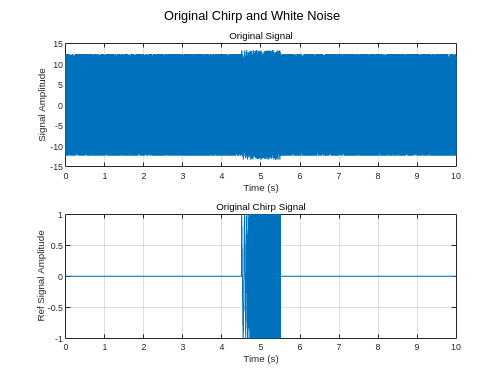

% --Location of signal start
    [~, location_start] = findpeaks(ref_chirp_long, "NPeaks",1);

% --Plotting out signals
    figure()
    subplot(2,1,1)
    plot(time, white_signal)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        subtitle("Original Signal")

    subplot(2,1,2)
    plot(time, ref_chirp_long)
        hold on
        grid on
        xlabel("Time (s)")
        subtitle("Original Chirp Signal")
        sgtitle("Original Chirp and White Noise")
        ylabel("Ref Signal Amplitude")

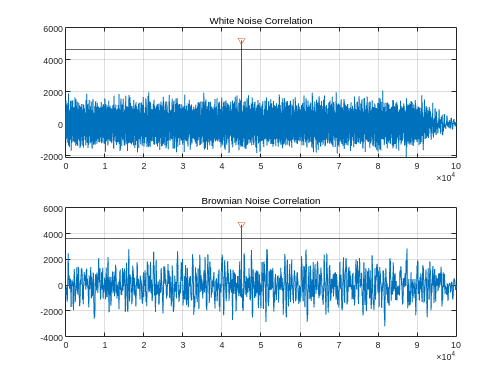

% --Correlation of data
    corr_out_white = xcorr(white_signal, reference');
    corr_out_white = corr_out_white(round(length(corr_out_white)/2):end);
    corr_mean_white = mean(abs(corr_out_white));
    threshold_white = max(corr_out_white) - 1.5*corr_mean_white;

    % --Finding Max
        [Iw,Jw] = find(corr_out_white == max(corr_out_white));

    corr_out_brown = xcorr(brown_signal, reference');
    corr_out_brown = corr_out_brown(round(length(corr_out_brown)/2):end);
    corr_mean_brown = mean(abs(corr_out_brown));
    threshold_brown = max(corr_out_brown) - 1.5*corr_mean_brown;

    % --Finding Max
        [Ib,Jb] = find(corr_out_brown == max(corr_out_brown));

% --Plot
    figure()
    subplot(2,1,1)
    plot(corr_out_white)
        hold on
        grid on
        xlim([0 100000])
        subtitle("White Noise Correlation")
        plot(Jw,max(corr_out_white),"V")
        yline(threshold_white)

    subplot(2,1,2)
    plot(corr_out_brown)
        hold on
        grid on
        xlim([0 100000])
        plot(Jb, max(corr_out_brown), "V")
        yline(threshold_brown)
        subtitle("Brownian Noise Correlation")

% --Detection criteria for white noise detection
    [peaks, index] = findpeaks(corr_out_white, 'MinPeakHeight', threshold_white, 'MinPeakDistance',100);
    peak = [peaks; 
            index];
    max_peak = max(peaks);
    [~, J] = find(peak == max_peak);

    if abs(peak(2,J) - location_start) <= 50
        fprintf("Yes")
    else
        fprintf("No")
    end

Yes

% --Detection criteria for brown noise detection
    [peaks, index] = findpeaks(corr_out_brown, 'MinPeakHeight', threshold_brown, 'MinPeakDistance',100);
    peak = [peaks; 
            index];
    max_peak = max(peaks);
    [~, J] = find(peak == max_peak);

    if abs(peak(2,J) - location_start) <= 50
        fprintf("Yes")
    else
        fprintf("No")
    end

Yes

This seems to be good enough to accurately detect if there is a signal that is detected, and I think this is how we will be finding the peaks. 

###         Matched Filters:

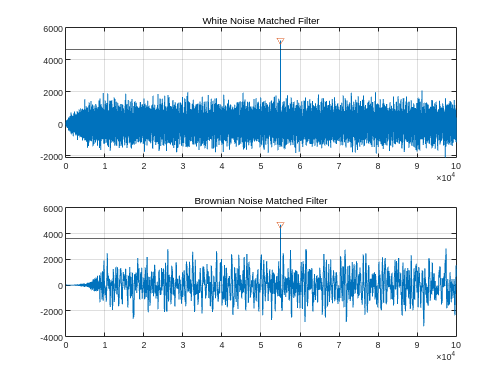

% --Matched Filtering
    ref_flip = conj(fliplr(reference'));

    white_matched = filter(ref_flip, 1, white_signal);
    white_matched_mean = mean(abs(white_matched));
    threshold_white = max(white_matched) - 1.5*white_matched_mean;

    % --Max value of the matched filter
        [Iw,Jw] = find(white_matched == max(white_matched));

    brown_matched = filter(ref_flip, 1, brown_signal);
    brown_matched_mean = mean(abs(brown_matched));
    threshold_brown = max(brown_matched) - 1.5*brown_matched_mean;

    % --Max value of matched filter output
        [Ib,Jb] = find(brown_matched == max(brown_matched));

% --Plot
    figure()
    subplot(2,1,1)
    plot(white_matched)
        hold on
        grid on
        xlim([0 100000])
        yline(threshold_white)
        plot(Jw, max(white_matched), "V")
        subtitle("White Noise Matched Filter")

    subplot(2,1,2)
    plot(brown_matched)
        hold on
        grid on
        xlim([0 100000])
        yline(threshold_brown)
        plot(Jb, max(brown_matched), "V")
        subtitle("Brownian Noise Matched Filter") 

% --Detection criteria for white noise detection
    [peaks, index] = findpeaks(white_matched, 'MinPeakHeight', threshold_white, 'MinPeakDistance',100);
    peak = [peaks; 
            index];
    max_peak = max(peaks);
    [~, J] = find(peak == max_peak);

    if abs(peak(2,J) - 55001) <= 50
        fprintf("Yes")
    else
        fprintf("No")
    end

Yes

% --Detection criteria for white noise detection
    [peaks, index] = findpeaks(brown_matched, 'MinPeakHeight', threshold_brown, 'MinPeakDistance',100);
    peak = [peaks; 
            index];
    max_peak = max(peaks);
    [~, J] = find(peak == max_peak);

    if abs(peak(2,J) - 55001) <= 50
        fprintf("Yes")
    else
        fprintf("No")
    end

Yes

The mathematical representation of our statistical check looks something like this:

$ A = \{p \mid p > max(x(t)) - \sigma, \forall p \in x(t)\}$ gives us the set of all peaks above the threshold and $B = \{p \mid y'(t) = 0, y''(t) <0, \forall p \in y(t)\}$gives us the max peaks in the reference set. We then say that there is signals detection if the location of $max(A)$ happens at the same spot as $B_1 \pm \lambda$. Putting this into words, we are basically saying that if the maximum of the correlation doesn't occur at the same spot as where the reference signal starts, then it is erroneous, and the peak is due to noise and no signal is detected in that location. 